clc
clearvars

% location of motors
n_motors = 6;
motor_locations = zeros(n_motors,2);
center_dist = 1;
theta = pi/2;
for motor = 1:n_motors
    [x,y] = pol2cart(theta,center_dist);
    motor_locations(motor,1) = x;
    motor_locations(motor,2) = y;
    theta = theta + 2*pi/n_motors;
end


## Main


origin = [0,0];
new_point = [.5,.6];
cable_lengths = ones(n_motors,1);


% calculate velocity and time to get there
% get from origin to new point at 1 m/s
[velocity, travel_time] = solve_velocity(motor_locations,origin,new_point,1)

velocity =    -0.4605
    0.4733
    0.9652
    0.8659
    0.2040
   -0.7945


travel_time = 0.7810

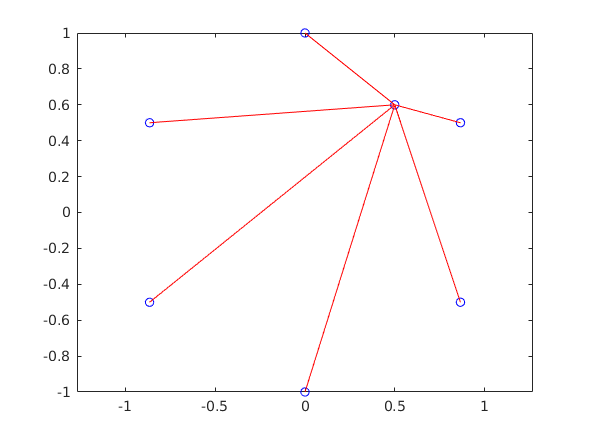

n_step = 100;
t_step = travel_time/n_step;
x_step = linspace(origin(1),new_point(1),n_step);
y_step = linspace(origin(2),new_point(2),n_step);

error = zeros(n_step,n_motors);

figure
for i = 1:n_step
    % calculate new cable lengths
    point = [x_step(i),y_step(i)];
    error(i,:) = plot_all(motor_locations,cable_lengths,point);
    cable_lengths = cable_lengths + velocity.*t_step;
    
end

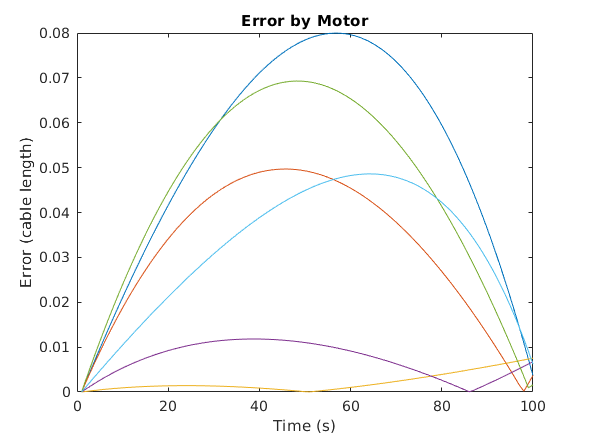


% plot error
figure
for i = 1:n_motors
    plot(error(:,i)), hold on
end
xlabel('Time (s)')
ylabel('Error (cable length)')
title('Error by Motor')

function plot_point(point)
    plot(point(1),point(2),'ob')
end

function [error] = plot_line(origin,destination,length)
    angle = atan2(destination(2)-origin(2), destination(1)-origin(1));
    real_destination = [origin(1) + length*cos(angle), origin(2) + length*sin(angle)];
    x = [origin(1),real_destination(1)];
    y = [origin(2), real_destination(2)];
    plot(x,y,"-r")
    
    % calculate error
    error = sqrt((real_destination(2)-destination(2))^2 + (real_destination(1)-destination(1))^2);
    
end

function [velocity, time] = solve_velocity(motor_locations,origin,destination,velocity)
    overall_distance = sqrt((origin(2)-destination(2))^2 + (origin(1)-destination(1))^2);
    time = overall_distance*(1/velocity);
    
    motor_origin_dist = sqrt((motor_locations(:,2)-origin(2)).^2 + (motor_locations(:,1)-origin(1)).^2);
    motor_destination_dist = sqrt((motor_locations(:,2)-destination(2)).^2 + (motor_locations(:,1)-destination(1)).^2);
    motor_travel = motor_destination_dist - motor_origin_dist;
    
    velocity = motor_travel/time;
end

function error = plot_all(motor_locations,cable_lengths,point)
    error = zeros(1,6);%% make sure to change this to n_motors
    plot_point(point), hold on, axis equal
    
    for i = 1:length(motor_locations)
        plot_point(motor_locations(i,:))
        error(1,i) = plot_line(motor_locations(i,:),point,cable_lengths(i,:));
    end
    hold off
    drawnow
    
end